L_i = 1.2e-3;        % H
L_g = 0.7e-3;        % H
C_f = 9e-6;          % F
R_d = 8;             % Ohms

omega_0 = 2*pi*50;   % rad/sec
omega_c = 0.5;       % rad/sec
omega_c3 = 2.5;
omega_c5 = 4.5;
omega_c7 = 10;

s = tf('s');

T_S = 1e-6;          % s
G_D = (1/(1+T_S*s));
G = ((1/(L_i*s))*(((s^2)+(s*R_d/L_g)+(1/(L_g*C_f)))/((s^2)+(s*((L_i*R_d+L_g*R_d)/(L_i*L_g)))+((L_i+L_g)/(L_i*L_g*C_f)))))*G_D

G =
 
              0.0007 s^2 + 8 s + 1.111e05
  ---------------------------------------------------
  8.4e-13 s^4 + 8.552e-07 s^3 + 0.01541 s^2 + 211.1 s
 
Continuous-time transfer function.




C = @(K) K(1) + ...
         K(2)*((2*omega_c*s)/((s^2) + (2*omega_c*s) + (omega_0^2))) + ...
         K(3)*((2*omega_c3*s)/((s^2) + (2*omega_c3*s) + ((3*omega_0)^2))) + ...
         K(4)*((2*omega_c5*s)/((s^2) + (2*omega_c5*s) + ((5*omega_0)^2))) + ...
         K(5)*((2*omega_c7*s)/((s^2) + (2*omega_c7*s) + ((7*omega_0)^2)));

G_cl = feedback(G*C(K),1);

K_fp = [6.8  1498.72  211.208  83.867  40.834];

G_cl_fp = feedback(G*C(K_fp),1);

% Nastavení parametrů signálu
fs = 50000*2*pi; % vzorkovací frekvence
f0 = 50*2*pi; % hlavní frekvence signálu
t = 0:(1/fs):(1/f0); % časový vektor
U = 1; % amplituda signálu
H = 7; % max harmonicka

% x = U*square(2*pi*t*f0,50); % Obdélníkový signál

% Vytvoření základního sinusového signálu
x = U*sin(2*pi*f0*t);

h = 3:2:H;
for n = h
    x = x + (U*(1/n))*sin(2*pi*n*f0*t);
end

% Vykreslení vstupního signálu
plot(t,x);

pxx_norm_vstup = 100*(periodogram(x,[],length(x),fs))/(max(periodogram(x,[],length(x),fs))); % normalizace hodnot na procenta

y = lsim(G_cl,x,t);
pxx_norm_vystup = 100*(periodogram(y,[],length(x),fs))/(max(periodogram(y,[],length(x),fs))); % normalizace hodnot na procenta

y_fp = lsim(G_cl_fp,x,t);
pxx_norm_vystup_fp = 100*(periodogram(y,[],length(x),fs))/(max(periodogram(y,[],length(x),fs))); % normalizace hodnot na procenta


thd = 0;
for n = 4:2:(2*length(h))+2
    fprintf("THD " + num2str(n-1) + ". harmonické je: %0.2f%%\n",pxx_norm_vstup(n));
    thd = thd + pxx_norm_vstup(n);
end

THD 3. harmonické je: 11.09%
THD 5. harmonické je: 3.97%
THD 7. harmonické je: 2.00%



fprintf('THD je: %0.2f%%\n',thd);

THD je: 17.06%


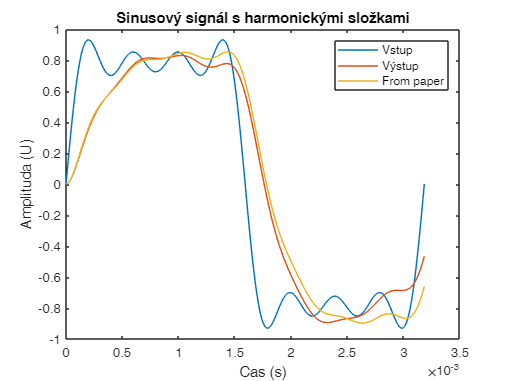


hold on
plot(t,y);
plot(t,y_fp);
title('Sinusový signál s harmonickými složkami');
xlabel('Cas (s)');
ylabel('Amplituda (U)');
legend("Vstup","Výstup","From paper")


thd = 0;
for n = 4:2:(2*length(h))+2
    fprintf("THD " + num2str(n) + ". harmonické je: %0.2f%%\n",pxx_norm_vystup(n));
    thd = thd + pxx_norm_vystup(n);
end

THD 4. harmonické je: 2.41%
THD 6. harmonické je: 0.40%
THD 8. harmonické je: 0.19%


fprintf('THD je: %0.2f%%\n',thd);

THD je: 2.99%



for n = 4:2:(2*length(h))+2
    fprintf("THD " + num2str(n) + ". harmonické je: %0.2f%%\n",pxx_norm_vystup_fp(n));
    thd = thd + pxx_norm_vystup_fp(n);
end

THD 4. harmonické je: 2.41%
THD 6. harmonické je: 0.40%
THD 8. harmonické je: 0.19%


function thd = spectral_density(sys, x,  t, fs, n)
y = lsim(sys,x,t);
pxx = periodogram(y,[],length(x),fs);
pxx = 100*(pxx)/(max(pxx)); % normalizace hodnot na procenta

thd = 0;
for nn = n
    thd = thd + pxx(nn);
end
end